# Simple script to generate DLV model data

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of “neurons” (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.3 1 3 10]; % Time constants (in seconds) for each OU field
%ones(1, param.N_F); % controls the time constants of the latents
param.T = 10; % Total simulation time (in seconds)

% ordered_J_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F);
% ordered_J_if(1:64, 2:4) = 0;
% ordered_J_if(65:128, [1 3 4]) = 0;
% ordered_J_if(129:192, [1 2 4]) = 0;
% ordered_J_if(193:end, [1 2 3]) = 0;

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 2.67*param.eta_val; % “Inverse temperature” and silence bias

[s_i, param, h_f] = sampleMorrellModel(param);

## Visualizing the Raw data and the latent variables

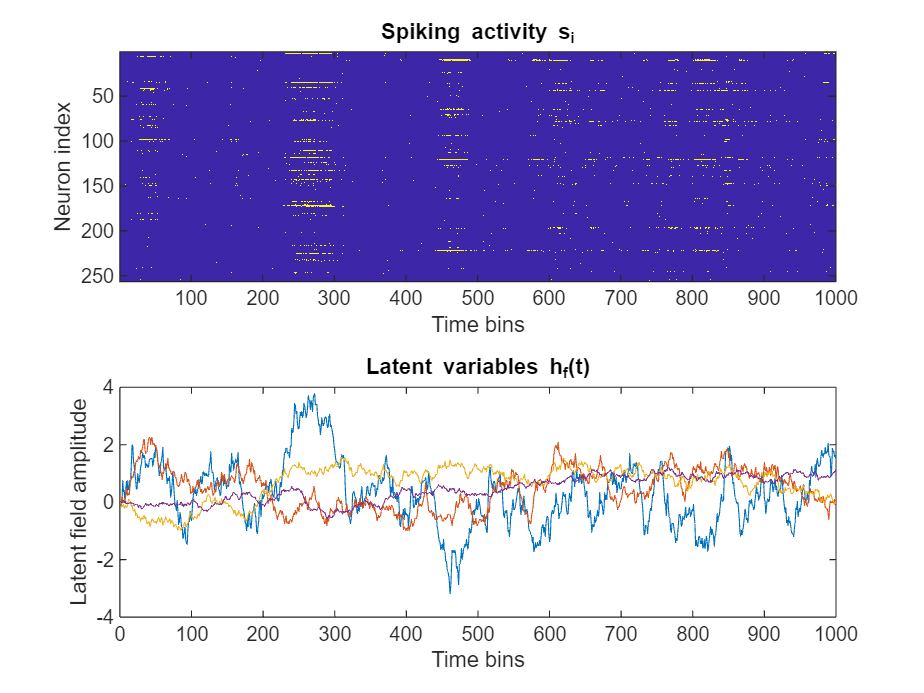

figure()
nexttile
imagesc(s_i)
xlabel('Time bins')
ylabel('Neuron index')
title('Spiking activity s_i')

nexttile
plot(h_f)
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')

## looking at PCA and relationship to ground truth (h_f, J_if)

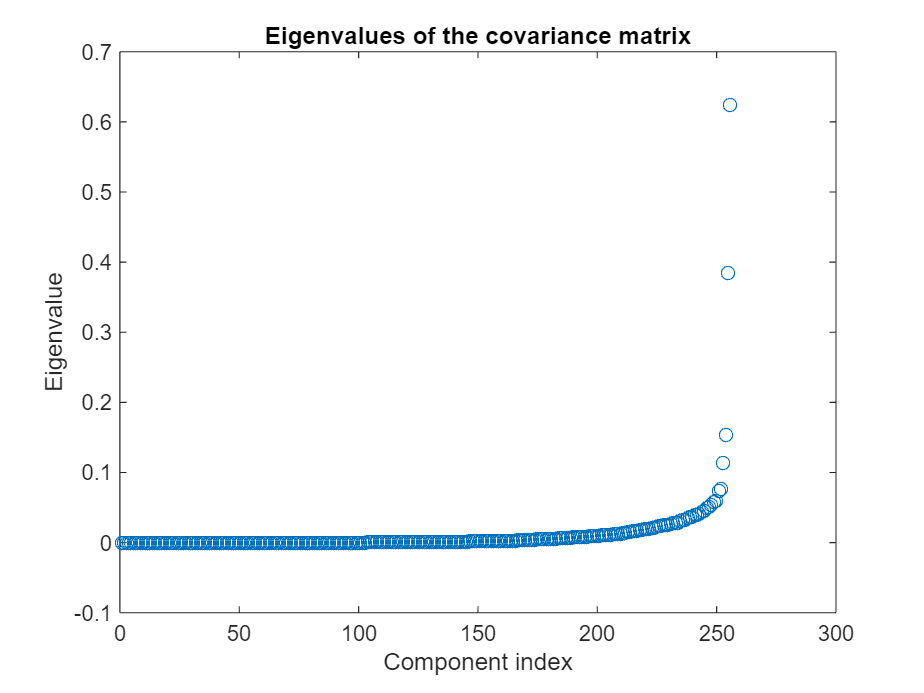

% getting the eigenvalues of covariance matrix
eig_vals = eig(cov(s_i'));
figure() 
plot(eig_vals, 'o')
xlabel('Component index')
ylabel('Eigenvalue')
title('Eigenvalues of the covariance matrix')

warning('off', 'MATLAB:rankDeficientMatrix')


[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(double(s_i'));

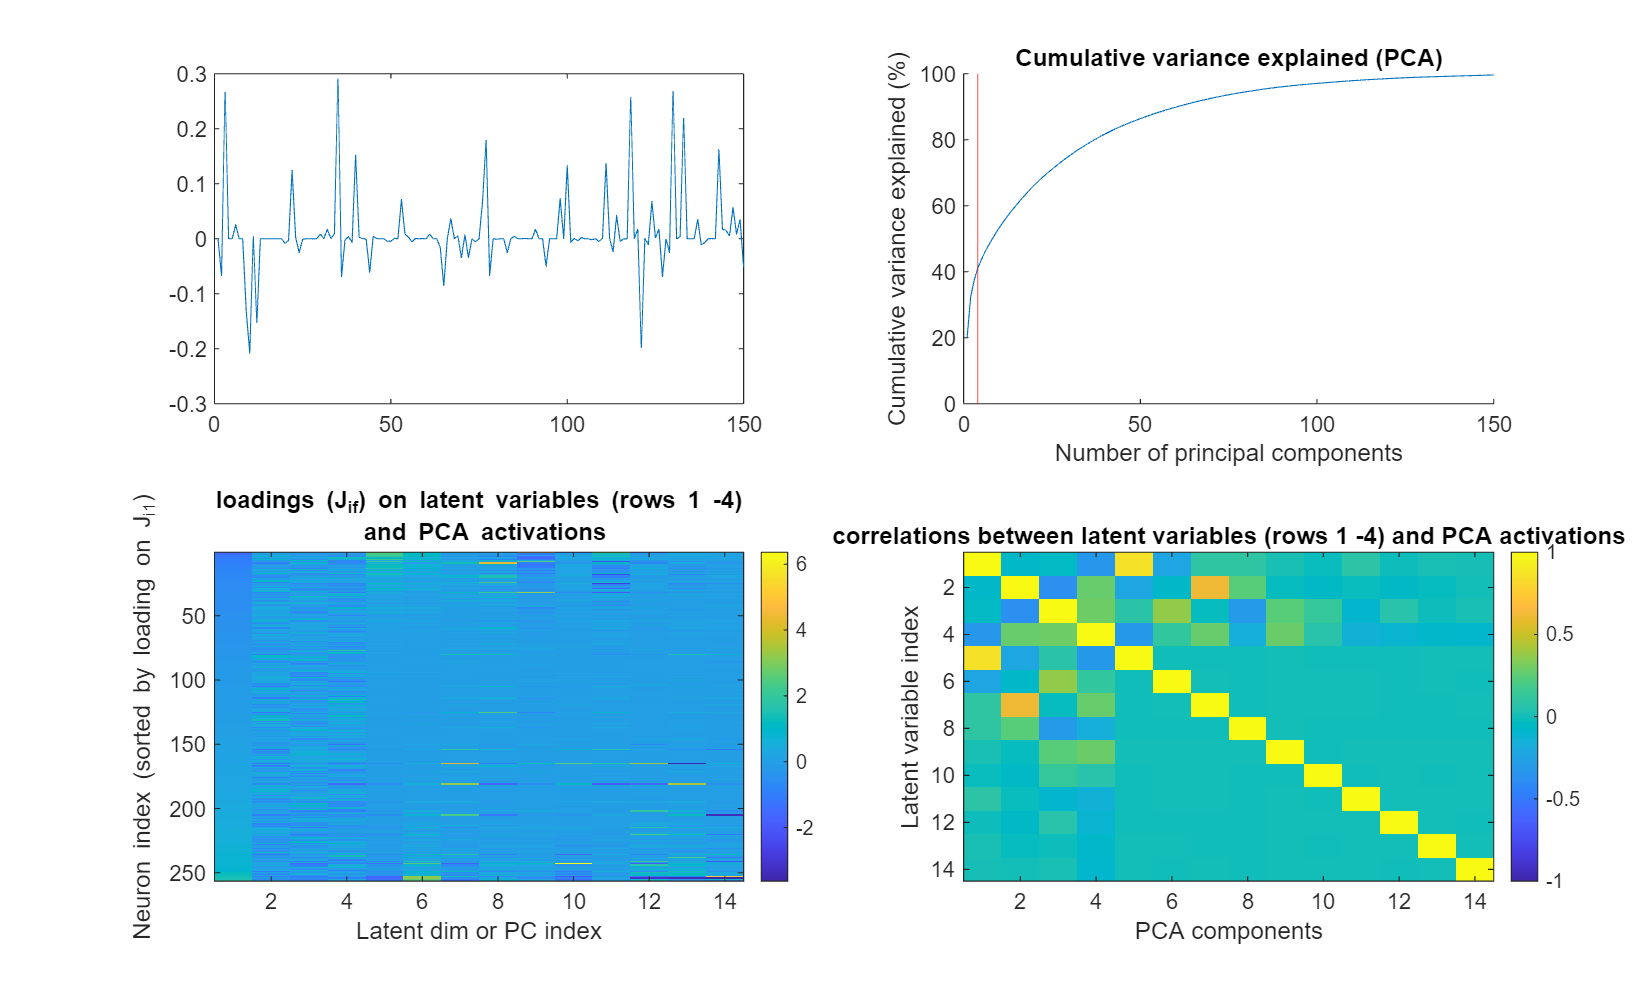

num_comp = 150;

figure('Position', [100 100 1000 600]) 
nexttile
plot(1:num_comp, COEFF(1:num_comp));


nexttile
hold on;
plot(cumsum(EXPLAINED))
xlim([0 150]);
ylim([0 100]);
xline(4, 'Color','r');
xlabel('Number of principal components')
ylabel('Cumulative variance explained (%)')
title('Cumulative variance explained (PCA)')

nexttile
[~, ord1] =sort(param.fixJ_if(:, 1)); % Sorting the neurons by their true coupling to latent 1
% Showing side-by-side the true J_i,m versus the first 10 PCA oadings
% rescaled 
imagesc([param.fixJ_if(ord1, :) COEFF(ord1, 1:10)*sqrt(param.N_neur/param.N_F)])
xlabel('Latent dim or PC index')
ylabel('Neuron index (sorted by loading on J_{i1})')
title({['loadings (J_{if}) on latent variables (rows 1 -' num2str(param.N_F) ')']; ... 
    ' and PCA activations'}, 'interpreter', 'tex')
colorbar

% Correlation between latent fields and PCA activations
cc_mat = corrcoef([h_f SCORE(:, 1:10)]);
nexttile
imagesc(cc_mat, [-1 1])
xlabel('PCA components')
ylabel('Latent variable index')
title(['correlations between latent variables (rows 1 -' num2str(param.N_F) ') and PCA activations'])
colorbar

## Simulate a "readout" of the population activity and look at the power spectrum

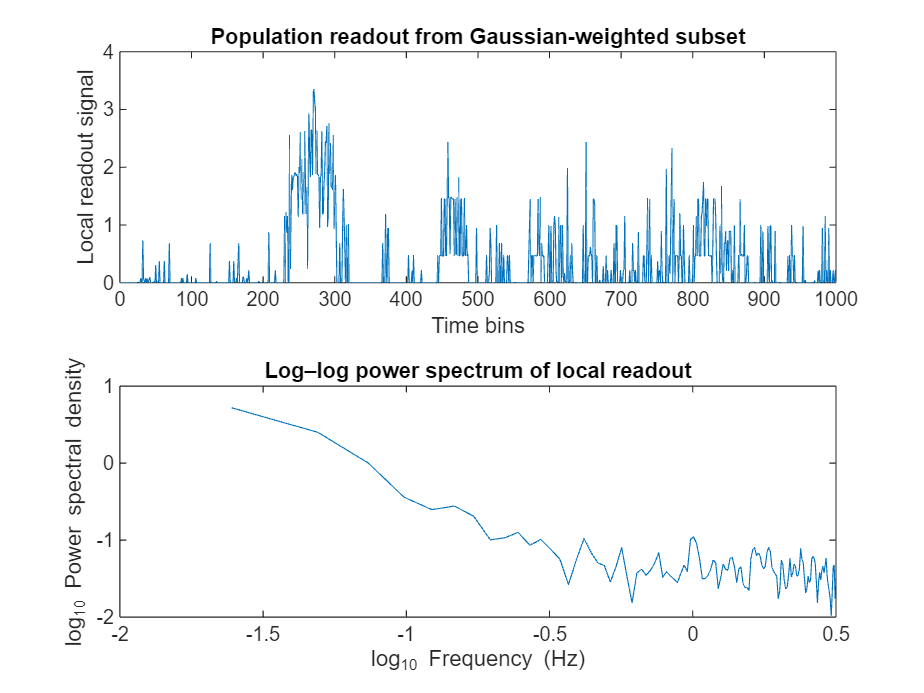

neuron_locations = 1:param.N_neur;
center_loc = 128;
nbhd_width = 32;
w_readout = exp(- (neuron_locations - center_loc).^2/(2*nbhd_width));

local_readout = w_readout*s_i;

figure()
nexttile
plot(local_readout)
xlabel('Time bins')
ylabel('Local readout signal')
title('Population readout from Gaussian-weighted subset')

[psd, f_psd] = pwelch(local_readout);
nexttile
plot(log10(f_psd), log10(psd))
xlabel('log_{10} Frequency (Hz)')
ylabel('log_{10} Power spectral density')
title('Log–log power spectrum of local readout')